# *Diagrama dos Esforços Resistentes*

### Determinação da contribuição do aço

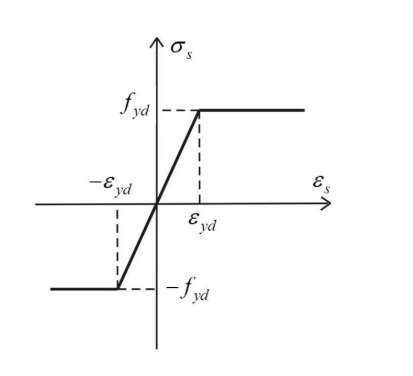

### Contribuição do Aço

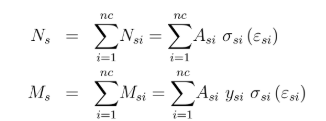

CA = 50;
f_yk = 500;
f_yd = f_yk /1.15 *10^6;
e_yd = 1000*f_yd/(210*10^9); 

### Contribuição do Concreto

C = 30;
fck = 30000000; 
e_cu = ecu(fck,C);
e_c2 = ec2(fck,C);
clear;

tipoc = 60;
fck = tipoc;
tipos = 50;

Definição da geometria da seção

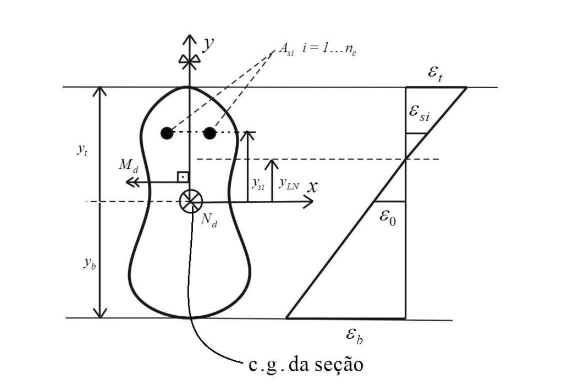

%altere aqui:

b = 0.2;
h = 0.6;
ytopo = +h/2;
ybase = -h/2;
diametro_bitola = 32*10^-3;
nc = 3;
ys = [-0.26 0.14 0.26];
ysmin = ys(1);
ysmax = ys(nc);
nbarras = [2 2 2];
n_concreto = n(fck*10^6,tipoc);


Definição do espaço a ser desenvolvido

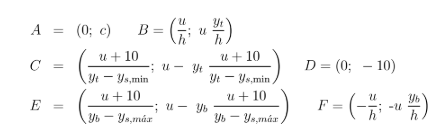

epsiloncu = ecu(fck*10^6,tipoc);
epsilonc2 = ec2(fck*10^6,tipoc);

u = epsiloncu;
c2 = epsilonc2;

A = [0.0 c2];
B = [u/h u*ytopo/h];
C = [(u+10.0)/(ytopo-ysmin) u-ytopo*(u+10.0)/(ytopo-ysmin)];
D = [0 -10.0];
E = [(u+10.0)/(ybase-ysmax) u-ybase*(u+10.0)/(ybase-ysmax)];
F = [-u/h -u*ybase/h];


## Plotagem do Gráfico

(o algoritmo é da aula do sérgio)

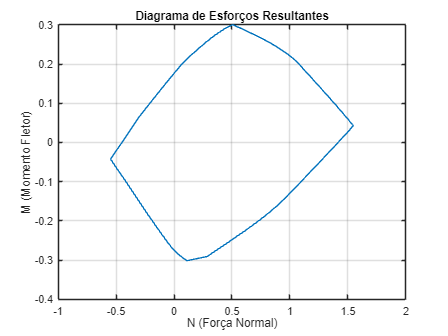

pontos = 1000;
incremento= 1/(pontos -1);
i = 1;
for s = 0:incremento:1
    if s <= 1/6
        c1(1) = A(1);
        c1(2) = A(2);
        ca(1) = 6.0*(B(1)-A(1));
        ca(2) = 6.0*(B(2)-A(2));
        k = ca(1)*s + c1(1);
        epsilon0 = ca(2)*s + c1(2);
        [v(i), u(i)] = esforcosresistivos(tipoc, tipos,b,h,diametro_bitola,nc,ys,nbarras,epsilon0,k,epsilonc2,epsiloncu,n_concreto);
    else 
        if s<= 2/6
            c1(1) = 2.0*B(1)-C(1);
            c1(2) = 2.0*B(2)-C(2);
            ca(1) = 6.0*(C(1)-B(1));
            ca(2) = 6.0*(C(2)-B(2));
            k = ca(1)*s + c1(1);
            epsilon0 = ca(2)*s + c1(2);
            [v(i), u(i)] = esforcosresistivos(tipoc, tipos,b,h,diametro_bitola,nc,ys,nbarras,epsilon0,k,epsilonc2,epsiloncu,n_concreto);
        else 
            if s <= 3/6
                c1(1) = 3.0*C(1)-2.0*D(1);
                c1(2) = 3.0*C(2)-2.0*D(2);
                ca(1) = 6.0*(D(1)-C(1));
                ca(2) = 6.0*(D(2)-C(2));
                k = ca(1)*s + c1(1);
                epsilon0 = ca(2)*s + c1(2);
                [v(i), u(i)] = esforcosresistivos(tipoc, tipos,b,h,diametro_bitola,nc,ys,nbarras,epsilon0,k,epsilonc2,epsiloncu,n_concreto);
            else
                if s <= 4/6
                    c1(1) = 4.0*D(1)-3.0*E(1);
                    c1(2) = 4.0*D(2)-3.0*E(2);
                    ca(1) = 6.0*(E(1)-D(1));
                    ca(2) = 6.0*(E(2)-D(2));
                    k = ca(1)*s + c1(1);
                    epsilon0 = ca(2)*s + c1(2);
                    [v(i), u(i)] = esforcosresistivos(tipoc, tipos,b,h,diametro_bitola,nc,ys,nbarras,epsilon0,k,epsilonc2,epsiloncu,n_concreto);
                else
                    if s <= 5/6
                        c1(1) = 5.0*E(1)-4.0*F(1);
                        c1(2) = 5.0*E(2)-4.0*F(2);
                        ca(1) = 6.0*(F(1)-E(1));
                        ca(2) = 6.0*(F(2)-E(2));
                        k = ca(1)*s + c1(1);
                        epsilon0 = ca(2)*s + c1(2);
                        [v(i), u(i)] = esforcosresistivos(tipoc, tipos,b,h,diametro_bitola,nc,ys,nbarras,epsilon0,k,epsilonc2,epsiloncu,n_concreto);
                    else
                        if s <= 6/6
                            c1(1) = 6.0*F(1)-5.0*A(1);
                            c1(2) = 6.0*F(2)-5.0*A(2);
                            ca(1) = 6.0*(A(1)-F(1));
                            ca(2) = 6.0*(A(2)-F(2));
                            k = ca(1)*s + c1(1);
                            epsilon0 = ca(2)*s + c1(2);
                            [v(i), u(i)] = esforcosresistivos(tipoc, tipos,b,h,diametro_bitola,nc,ys,nbarras,epsilon0,k,epsilonc2,epsiloncu,n_concreto);
                        end
                    end
                end
            end
        end
    end
    i = i+1;
end
plot(v, u);
hold on;
grid on;
title('Diagrama de Esforços Resultantes'); % Adiciona título
xlabel('N (Força Normal)'); % Rótulo do eixo X
ylabel('M (Momento Fletor)'); % Rótulo do eixo Y